## 地震に対する建物の応答をどの様に決定するか。

地震の時に、構造物は地面を通して伝わってくる地震波に応答して振動する。深刻な地震の時は、構造物は損傷又は崩壊の可能性がある。

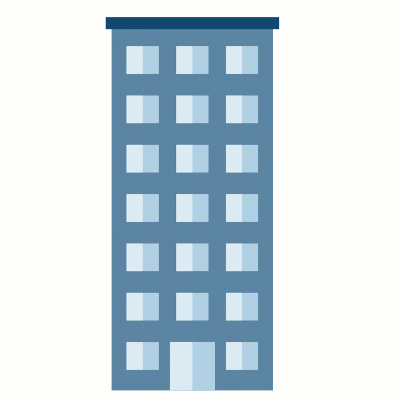

では、どのように建物は地震波に応答するか。その答えは動的モデリングにある。このスクリプトでは、二重バネマスダンパーシステムを用いて、シミュレーションで生成した地震波に対する2階建て建物の応答を分析する。

# 二重 バネ・マスダンパー

clear % This clears the MATLAB workspace each time you run the script
addModelPaths % This helper adds the model paths

このセクションを実行することで、本モデルが入っているフォルダーをMATLAB検索パスに追加することができる。この動作はモデルを実行する為に必要である。

## 1. 二重バネマスダンパーモデル

この二重バネマスダンパーモデルは２つのバネマスダンパーを1つのシステムに含んでいる。このシステムは２自由度（DOF）があり$x_1$と$x_2$とする。下図のシステムは、重りのうちひとつだけがバネ・ダンパーを介して剛体面に接続している。

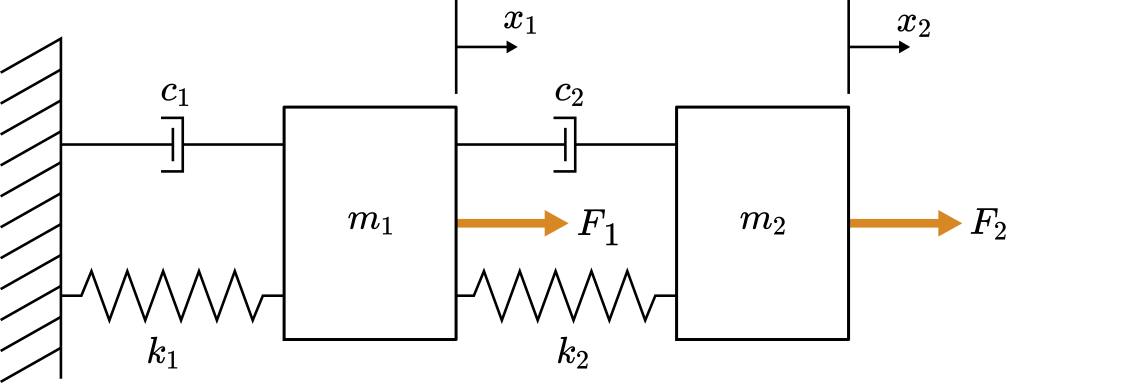

*二重バネマスダンパーシステム図*

パラメータは、それぞれ二つあることを除いて、単一のバネマスダンパーと同じである。

- $k_1 ,k_2$: ばね剛性 [N/m]

- $c_1 ,c_2$: 減衰係数 [N$\cdot$s/m]

- $m_1 ,m_2$: 質量 [kg]　　　　　

- $F_1 ,F_2$: 外力[N] (一定か時間依存: $F(t)$)

系の時間に依存した振る舞いは、以下の変数を用いて記述される。

- $t$: シミュレーション開始からの時間 [s]　

- $x_1 ,x_2$: 時間依存($x_i=x_i(t)$) 基準となる平衡位置からの質量の変位 [m]　

力をどちらかの重りに与えると、振動が起きる。2つの重り間でエネルギーは伝達し、ダッシュポットが系のエネルギーを減少させ、時間の経過とともに振動は減少する。

 ** Try**

- 紙に、力が両方の重り$m_1$と$m_2$に及ぼしている自由物体図を書きなさい

- 力を加える方向を決める時は注意しなさい。各バネの力がどの方向にはたらくかを$x_i$が向く方向を基に考えなさい。圧縮されたバネは外にはたらく力が生まれる一方、伸びたバネは内にはたらく力が生まれる。

- 自由物体図を描いた後、ニュートンの第２法則を用いて運動方程式を作成しなさい。     

                $m_1\ddot{x}_1 \;=\;\;\sum Forces$   and   $m_2\ddot{x}_2 \;=\;\;\sum Forces$.

showSolutionFBD = true; % Click the checkbox to view the solution
if(showSolutionFBD)
    clf
    I = imread("images/doubleMSDFreeBodyDiagram.png");
    imshow(I);
end

## 2. 連立常微分方程式（ODE）システムをMATLABで動かす

前回のセクションで作成した二重バネマスダンパーの微分方程式は以下の通りである。

    
$$m_1 \ddot{x}_1 = F_1 + k_2(x_2 - x_1) + c_2 (\dot{x}_2 - \dot{x}_1) - k_1 x_1 - c_1 \dot{x}_1$$


    
$$m_2 \ddot{x}_2 = F_2 - k_2(x_2 - x_1) - c_2 (\dot{x}_2 - \dot{x}_1)$$


この式をSimulinkで解くには、これらの式を評価するMATLAB Functionブロックを作成する。MATLABコマンドを使ってシンボリック計算をしてから、その結果を用いて、自動でMATLAB Functionブロックを生成する事が出来る。 

** Exercise. **この課題では、二重バネマスダンパーの連立常微分方程式のシンボリック表現と、Simulinkで評価可能なMATLAB Functionブロックを作成する。

**Task 1.** 二重バネマスダンパーの式を、事前定義されたシンボリックの変数を用いて書き、それぞれを`msdEq1,msdEq2`に代入しなさい。

  **Pro-tip**: シンボリック式を書く時に、式全体をMATLAB変数に割り当てる際　$=$　を使用する。つまり、シンボリック式での等号は以下で示されるように、==を使わなければならない。

syms x_1 x_2 x_dot_1 x_dot_2 x_ddot_1 x_ddot_2 m_1 m_2 k_1 k_2 c_1 c_2 F_1 F_2 % Symbolic variables for you to use
msdEq1 = m_1*x_ddot_1 == F_1 + k_2*(x_2 - x_1) + c_2*(x_dot_2 - x_dot_1) - k_1*x_1 - c_1*x_dot_1 % Replace NaN with the first equation
msdEq2 = m_2*x_ddot_2 == F_2 - k_2*(x_2 - x_1) - c_2*(x_dot_2 - x_dot_1) % Replace NaN with the second equation
checkMSDeq(msdEq1,msdEq2) % This helper function (located at the bottom of the script) checks your equation

**Task 2.** 関数[solve(equation, variable)](https://jp.mathworks.com/help/symbolic/solve.html)を使って最初の式`x_ddot_1`と2番目の式`x_ddot_2`を解き`、`結果を`expr1`と`expr2`に入力しなさい。この関数の中の`equation`はシンボリック式として`、variable`はシンボリック変数として解きなさい。

expr1 = solve(msdEq1,x_ddot_1) % Replace NaN with a call to solve()
expr2 = solve(msdEq2,x_ddot_2) % Replace NaN with a call to solve()
checkExpressions(expr1,expr2) % This helper function (located at the bottom of the script) checks your expressions

**Task 3.** Simulinkモデルの[mfbDouble.slx](matlab: open_system('models/mfbDouble'))を開く。

**Task 4. **完成したシンボリック式をSimulinkのMATLAB Funcionブロックに追加する。

一つの方法は、式をコピー&ペーストし、SimulinkでのMATLAB Function ブロックに入れることである。もう１つの方法は、MATLABの[`matlabFunctionBlock`](https://www.mathworks.com/help/symbolic/matlabfunctionblock.html) コマンドを使用してシンボリックの表現からブロックを自動に生成することである。

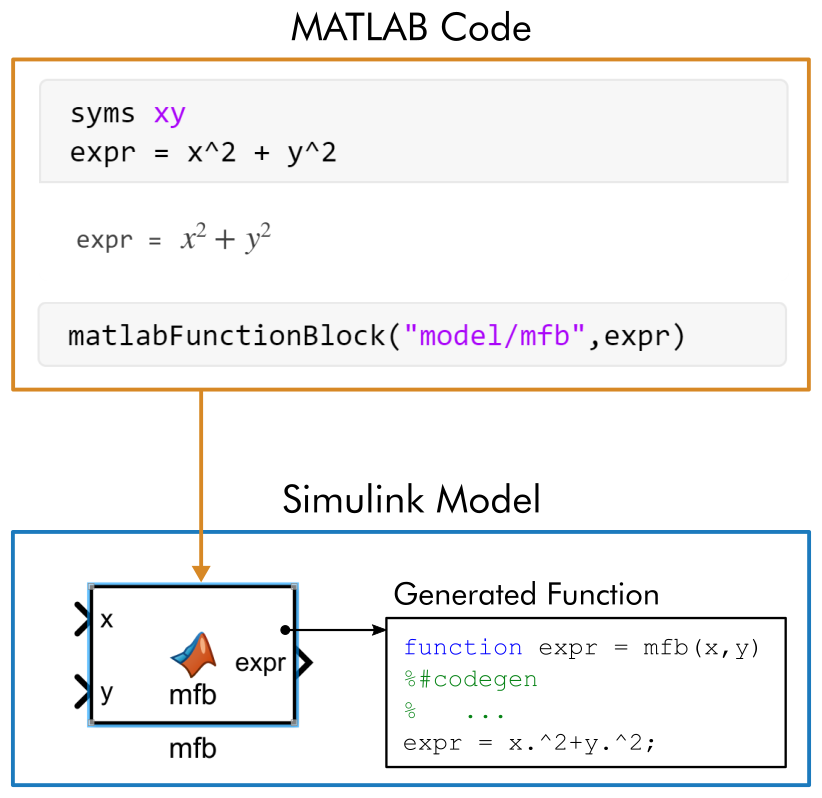

*シンボリック式からMATLAB Functionブロックを生成する際のmatlabFunctionBlockコマンド使用例*

下記の空いているスペースに、`matlabFunctionBlock`を呼ぶシンタックスを書きなさい。

上記のシンタックスで、以下の通り設定する。

- `modelName`をモデル名`mfbDouble`（.slxは含まない）に変更する

- `blockName`を好みのブロックの名前にする：`（例：double msd）`

- `f1``を``expr1``（`$\ddot{x}_1$のシンボリック表現）として変更。`f2も同様に行う`

- `"outputName1"と"outputName2"を``それぞれ``x_ddot_1` と `x_ddot_2`をにする

- `"Optimize" flag`を`false`に変更する

モデルは`matlabFunctionBlock`関数が動くように開いておく。

% This is the correct function call:
% matlabFunctionBlock("mfbDouble/doubleMassSpringDamper",expr1,expr2,"Outputs",["x_ddot_1","x_ddot_2"],"Optimize",false)

% (it has been commented out to avoid unwanted additions of the block)

**Task 5. **MATLAB Functionブロックが作成されたら、式を正しく評価するかテストする。

- MATLAB Functionブロックのサイズを大きくする。

- 各入力を各定数に接続し、出力を"check output"サブシステムに接続。

- モデルを実行して、Displayブロックを観察する。

## 3. 二重バネマスダンパ―モデルをSimulinkで解く

単一のバネマスダンパーを解く構成で、連立常微分方程式をSimulinkで解くことが出来る。MATLAB Functionブロックで式を定義し、integrtorブロックで時間統合する。

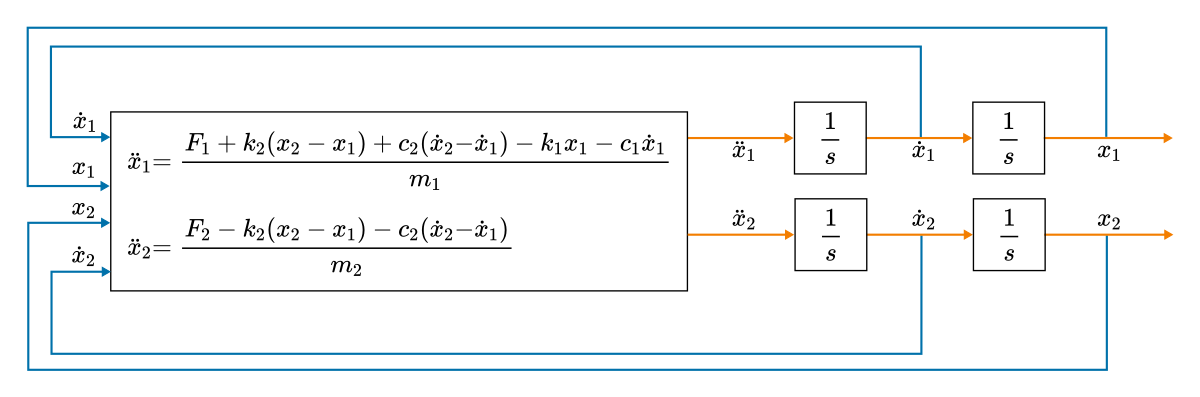

*この2自由度系では、単一のバネマスダンパーに比べて、2倍の数のintegratorブロックが必要となる*

** Exercise. **この課題では二重バネマスダンパーを解くSimulinkモデルを構築する。

- [msdDouble.slx](matlab: open_system('models/msdDouble'))を開く。

- 上記のブロック線図のように、4個のIntegratorブロックを追加・接続し、連立常微分方程式を解く。

- MATLAB Functionブロックに8個の入力を用意するために、8個のConstantブロックを追加する。それぞれの定数を下記のように設定する。

- $k_1 = 20$ N/m と $k_2 = 5$ N/m.

- $c_1 = 0.25$ N$\cdot$s/m と $c_2 = 0.5$ N$\cdot$s/m

- $m_1$ = 2 kg と $m_2 = 0.5$ kg

- $F_1 = F_2 = 0$ N

- Integratorブロックの初期値を$\dot{x}_1(0) = 0$, $\dot{x_2}(0) = 8$, $x_1(0)=0$, $x_2(0)=0$に設定する。

- Scopeブロックを追加し、$x_1$と$x_2$の信号に接続する。

- モデルを実行する。もし正しく動作したら、下記のような出力が確認できる。

もし問題があれば、完成したモデルを[msdDoubleSoln.slx](matlab: open_system('models/msdDoubleSoln'))でチェックする。

            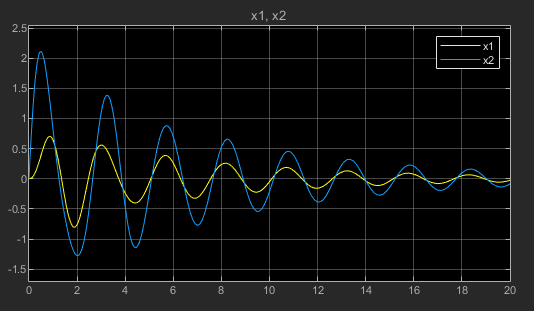

*          二重バネマスダンパー解答*

**二重バネマスダンパーの挙動を可視化する**

`msdDoubleSimulationOutput.slxの`モデルが完成すると、動きを可視化することができる。

n = 150; % The number of steps used in the visualization
visualize = true; % Click the checkbox to show the visualization
if(visualize)
    simOut = sim("models/msdDoubleSimulationOutput"); % simulates a completed double mass-spring-damper model
    animateMSD(simOut.tout,simOut.yout,0.75,n) % helper function that creates an animation of the output from the model
end

 ** Try **Simulinkモデルの[msdDoubleSimulationOutput.slx](matlab: open_system("msdDoubleSimulationOutput"))を開いて、 

- 2つ目のバネの剛性を高くする。そして、本セクションを再実行して、振る舞いにどのように影響したか観察する。

- 初期設定とパラメータを調整する。重り間で位相が反転した振動をおこすようなパラメータを見つけてみよう   [https://www.youtube.com/watch?v=Vqjbmj3SbPw](https://www.youtube.com/watch?v=Vqjbmj3SbPw)

## 4. 二重バネマスダンパーを用いたビルの振動モデル構築

地震は幾つかのタイプの地震波を生成し、地中と地面を伝わっていく。ラブ波はゆっくりと減衰するため、特に地震の震源地の外側では破壊的である。

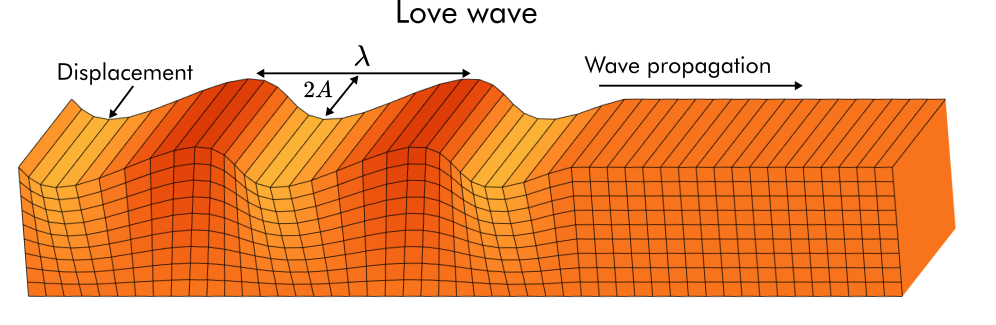

*ラブ波は地表で水平方向の変位を引き起こす。地表の下では、その大きさは急速に減衰する。*

この課題では、地震波による2階建て建物の水平方向の動きを分析する。複雑さを減らすため、以下の通り単純化した仮定を行う。

- 壁は柔軟で、質量はないものと仮定する。

- 床は、剛体重量物でバネダンパー（壁）を介して繋がっていると仮定する。　

- 水平方向の動きだけをモデル化する。

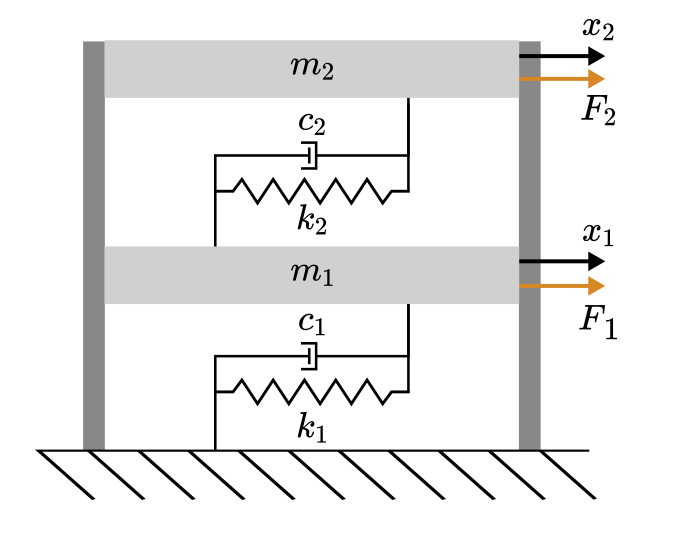

*2階建てビルの水平方向の動きを単純な2自由度のバネマスダンパーで理想化したモデル*

建物のモデルは下記の特徴を持っているものと仮定する。

- 有効質量: $m_1 =30,000\;\left\lbrack \textrm{kg}\right\rbrack$ と $m_2 =13,500\;\left\lbrack \mathrm{kg}\right\rbrack$　

- $k_1 =\;11\times {10}^6 \left\lbrack \frac{\mathrm{N}}{\mathrm{m}}\right\rbrack$, $k_2 =5\times {10}^6 \left\lbrack \frac{\mathrm{N}}{\mathrm{m}}\right\rbrack$

- $c_1 =\;2625\;\left\lbrack \frac{\mathrm{N}\cdot \;\mathrm{s}}{\mathrm{m}}\right\rbrack$, $c_2 =\;2475\;\left\lbrack \frac{\mathrm{N}\cdot \;\mathrm{s}}{\mathrm{m}}\right\rbrack$

地震波は周期的な強制力を最初の質量に与える事によってシミュレーションされる。

- $F_1 \left(t\right)=F_0 \;\sin \left(\frac{2\pi t}{T}\right)\;\;$ ここで、継続時間$[t_s,t_f]$, 周期 $T$、強制力の振幅 $F_0$,であり、後程設定する

- 
$$F_2 = 0$$


** Exercise**. この課題では、二重バネマスダンパーで表現されたビルモデルの固有周波数と、周期的な強制力に対する応答を分析する。

**Part 1. **構造物には、その構造によって決まる固有振動周期がある。このパートでは、バネマスダンパーによるビルモデルの固有振動周期を計測する。

- [msdDoubleBuilding.slx](matlab: open_system('models/msdDoubleBuilding'))を開く。

- モデルの初期条件を $x_1(0) = 0.1$, $x_2(0) = 0$, $\dot{x}_1(0) = 0$, $\dot{x}_2(0) = 0$に[mask image](matlab: hilite_system('msdDoubleBuilding/double mass-spring-damper'); pause(1); hilite_system('msdDoubleBuilding/double mass-spring-damper','none');)をダブルクリックして設定する。 

- 与える力がゼロである（[F0](matlab: hilite_system('msdDoubleBuilding/F0 [N]'); pause(1); hilite_system('msdDoubleBuilding/F0 [N]','none');) をゼロに設定）事を確認し、残ったパラメータを上記リスト通りに設定する。

- シミュレーションの終了時間を５秒に設定する。

- シミュレーションを実行する。

- [scope](matlab: hilite_system('msdDoubleBuilding/Scope msd'); pause(1); hilite_system('msdDoubleBuilding/Scope msd','none');)をみる。複数の振動周波数があることを確認し、2つ目の質量がほぼ規則的な周波数であることを確認する。その振動の周期を、$x_2$の最初の2つの絶対最小値を計ることによって求める。

 **Pro-tip**: 再スケールツール   をつかって、縦軸を再スケーリング出来る。

x2_period = 0.463; % [s] Record the period that you measured here
checkPart1(x2_period)

**Part 2. **このパートでは、2重バネマスダンパーに低周波数の強制力を与える。

- $F_0 = 7500$ N, $T = 25$ s, $t_s = 10$, $t_f = 110$に設定して、ラブ波をシミュレーションする。

- シミュレーション終了時間を150秒に設定する。

- モデルの初期値をゼロに設定する（($x_1(0) = 0$, $x_2(0) = 0$, $\dot{x}_1(0) = 0$, and $\dot{x}_2(0) = 0$)）。

- モデルのシミュレーションをする。もしパラメータが正しく設定してあれば、以下のような図がscopeで見えるはずである（scopeの軸を再スケーリングする必要がある   ）。

- scopeから$x_2$ の最小値を求め、以下に答えを入力する（単位：メートル）。scopeの軸の倍率（$\times 10^{-1}$)に注意

                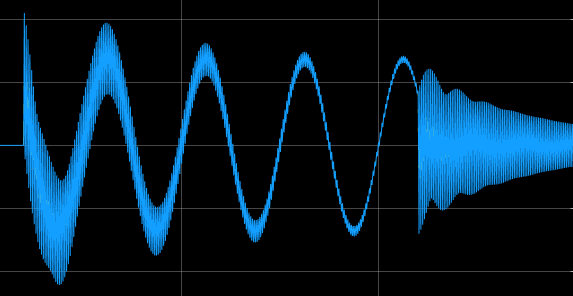

x2_disp = -0.0011;% [m] Record the minimum value of x_2
checkPart2(x2_disp)

 **Reflect:**

- この信号は2つのスケールがあり、急な振動とゆっくりな振動であるが、なにが原因でこうなるのか。

- 低周波数の強制力では約６ｍｍの変位がある。もし、地震波が違った周期を持っていたら、違った変化があったであろう。どの様な周期の力が加わると、より大きい変位をもたらすと考えられるか。

**Part 3. **もし、強制力の周波数が、共振周波数とよばれる構造物の固有周波数に近ければ、連続した振動が積み重なる。

- 他の地震波はより高い周波数を持っている。同じパラメータを維持して、周期を$T = 0.46$と設定し、結果を観察する。そして、$x_2$の変位の最大値を見積もり、以下に記入する（単位：メートル）

x2_max = 0.07;% m

Close enough!


checkPart3(x2_max)

 **Reflect:**

- 周期をT = 1.2に設定し、シミュレーションを再実行する。この小さい周期の変化であっても、振動の共振を減少させることを観察する。

- もし壁がより硬くなる（剛性パラメータの$k_i$を増やす）と、共振の周期は短くなるか、長くなるか。剛性を2倍にし、シミュレーションを再実行して、想定を試してみよ。

- 他にどの様な方法で、バネマスダンパーシステムの共振周波数を解けるだろうか。

### 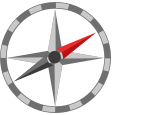**更なる探求のために**

Simscapeを使うことで、微分方程式の導出や連携を行わずにバネマスダンパーのシステムを解くことが出来る。この方法では、微分方程式を定義する代わりに、抽象的な機械システムのコンポーネン**ト**を使い、バネマスダンパーシステムを定義する。この方法を習いたい方は、下記のSimscapeドキュメンテーションを参照せよ。

- [Mass-Spring-Damper in Simulink and Simscape](https://www.mathworks.com/help/physmod/simscape/ug/mass-spring-damper-in-simulink-and-simscape.html) 

- [Double Mass-Spring-Damper in Simulink and Simscape](https://www.mathworks.com/help/physmod/simscape/ug/double-mass-spring-damper-in-simulink-and-simscape.html)

**Helper functions**

これらの関数は解答のチェックとアニメーションを作成する。

function correct = isEqualCheck(userSubmission,correctAnswer)
    correct = isEqualCheckCustom(userSubmission,correctAnswer,"Correct!","Your answer does not match the expected result.");
end

function correct = isEqualCheckCustom(userSubmission,correctAnswer,correctResponse,incorrectResponse)
    correct = true;
    if( isequal(userSubmission,correctAnswer) )
        disp(correctResponse)
    else
        warning(incorrectResponse)
        correct = false;
    end
end

function checkMSDeq(msdEq1User,msdEq2User)
    syms x_1 x_2 x_dot_1 x_dot_2 x_ddot_1 x_ddot_2 m_1 m_2 k_1 k_2 c_1 c_2 F_1 F_2
    msdEq1 = m_1*x_ddot_1 == F_1 + k_2*(x_2 - x_1) + c_2*(x_dot_2 - x_dot_1) - k_1*x_1 - c_1*x_dot_1; 
    msdEq2 = m_2*x_ddot_2 == F_2 - k_2*(x_2 - x_1) - c_2*(x_dot_2 - x_dot_1); 

    isEqualCheckCustom(solve(msdEq1User,x_ddot_1),solve(msdEq1,x_ddot_1),"First equation correct!","First equation not correct");
    isEqualCheckCustom(solve(msdEq2User,x_ddot_2),solve(msdEq2,x_ddot_2),"Second equation correct!","Second equation not correct");
end

function checkExpressions(expr1User,expr2User)
    syms x_1 x_2 x_dot_1 x_dot_2 x_ddot_1 x_ddot_2 m_1 m_2 k_1 k_2 k_3 c_1 c_2 c_3 F_1 F_2
    msdEq1 = m_1*x_ddot_1 == F_1 + k_2*(x_2 - x_1) + c_2*(x_dot_2 - x_dot_1) - k_1*x_1 - c_1*x_dot_1; 
    msdEq2 = m_2*x_ddot_2 == F_2 - k_2*(x_2 - x_1) - c_2*(x_dot_2 - x_dot_1);

    isEqualCheckCustom(expr1User,solve(msdEq1,x_ddot_1),"First expression correct!","First expression not correct");
    isEqualCheckCustom(expr2User,solve(msdEq2,x_ddot_2),"Second expression correct!","Second expression not correct");
end

function animateMSD(tin,xin,spacingMultiplier,steps) 
    
    Nmass = size(xin,2); % Number of masses

    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 1; % Mass width
    h = 2; % Height of masses
    y = 0; % Vertical position
     
    % Local variables
    t = linspace(tin(1),tin(end),steps);
    x = zeros(steps,Nmass);
    for k = 1:Nmass
        x(:,k) = interp1(tin,xin(:,k),t);
    end
    spacing = 2*max(abs(x),[],"all")*spacingMultiplier;
    xmax = spacing*2.5 + 2;
    
    % Loop to create the animation
    figure;    
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        x0k = 0;
        for k = 1:Nmass
            % Plot springs
            xc = spacing*k+x(j,k)-w/2;       
            xs = linspace(x0k,xc,12);
            ys = 0.25*(-1).^(1:numel(xs));
            plot(xs,ys + 0.5,"k");
            % Plot dampers
            yd = 1.65;
            xd = x0k + (xc-x0k)*0.5+0.1;
            xd2 = x0k + (xc-x0k)*0.5;
            xd3 = x0k + (xc-x0k)*0.5 + 0.2;
            plot([x0k,xd,NaN,xd,xd],[yd,yd,NaN,yd-0.1,yd+0.1],"k")
            plot([xd2,xd3,NaN,xd2,xd3,NaN,xd3,xd3,NaN,xd3,xc],[yd-0.15,yd-0.15,NaN,yd+0.15,yd+0.15,NaN,yd-0.15,yd+0.15,NaN,yd,yd],"k")
            % Update position
            x0k = xc + w;
            % Plot masses
            x1 = spacing*k + x(j,k) - 0.5;
            rectangle("Position",[x1 y w h],"FaceColor",colors(k,:))
            text(x1 + w/2, h/2,"m_" + num2str(k),"HorizontalAlignment","center","color","w")
            % Plot x1, x2 distances
            quiver(spacing*k, y+h*1.1, x(j,k),0,"k-","MaxHeadSize",1/(x(j,k))^2)
            plot([1;1]*[spacing*k, spacing*k+x(j,k)],[0.95;1.05]*(y*[1,1]+h*1.1),"k-","markersize",12)
            text((spacing*k + spacing*k+x(j,k) )/2,(y+h*1.3),"x_"+num2str(k),"HorizontalAlignment","Center")
        end
        hold off
        axis([0,xmax,-1,3])
        set(gca,"ytick",[])
        xlabel("reference axis [m]")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"ko","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x [m]")
        hold off
        box off
        drawnow
    end
end

function checkPart1(x2_period)
    if(abs(x2_period - 0.463) < 0.1)
        disp("Close enough!")
    else
        warning("Not close enough.") 
    end
end

function checkPart2(x2_disp)
    if(abs(x2_disp - (-0.0011)) < 0.001 )
        disp("Close enough!")
    else
        warning("Not close enough.") 
    end
end

function checkPart3(x2_max)
    if(abs(x2_max - 0.068) < 0.01 )
        disp("Close enough!")
    else
        warning("Not close enough.") 
    end
end

function addModelPaths()
    % Adds the paths for the models and images
    scriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
    addpath(scriptPath,scriptPath + "/images/",scriptPath + "/models/")
end

% Suppress unused suggestions
%#ok<*UNRCH> 
%#ok<*DEFNU> 